# ENGR105    ---    Problem Set 7    ---   Plotting, logicals, and recursion

## Due: Friday, 10/23/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW6.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

************ IMPORTANT: For HW7, please also submit the **`.m`** file requested in Problem 4. ***************************

- The LiveScript file may be exported to PDF using the **Save** dropdown menu. **Please also see my recent email regarding alternative methods for exporting to PDF.**

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Gain familiarity making more sophisticated plots, using `set()`/`get()`, and modifying graphics handles.

- Use recursion to solve a problem relevant to engineering.

- Apply logical indexing to more quickly analyze data and produce seemingly complicated plots.

- Understand provided code and produce appropriate add-ons.

- Produce our first simulations

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (35 pts): Plotting

Consider the following vectors, `t` and `f`.

% Two vectors provided for this problem: time and -sin(t)
t = -3*pi:pi/24:3*pi;   % time, -3pi to 3pi
f = -sin(t);    % function of time

Using only these **vectors **`t`** and **`f`**, logical indexing/math, element-wise vector addition/subraction/multiplication/division (and the appropriate code for formatting plots)**, produce each of the following plots. For each part, use the `plot()` function for all plots and ensure all plot formatting matches what is provided. Display your plots when you convert this Livescript file to a PDF.

**Hint 1**: remember `gca,` `gcf, `and` graphics object handles`

**Hint 2**: *current* graphics handle parameters for a set of axes may be viewed using `get(gca)`

**Example problem:**

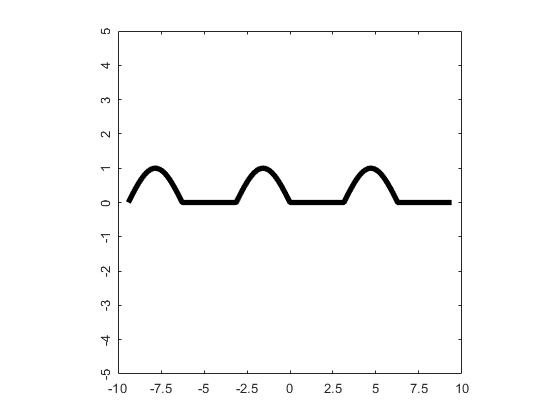

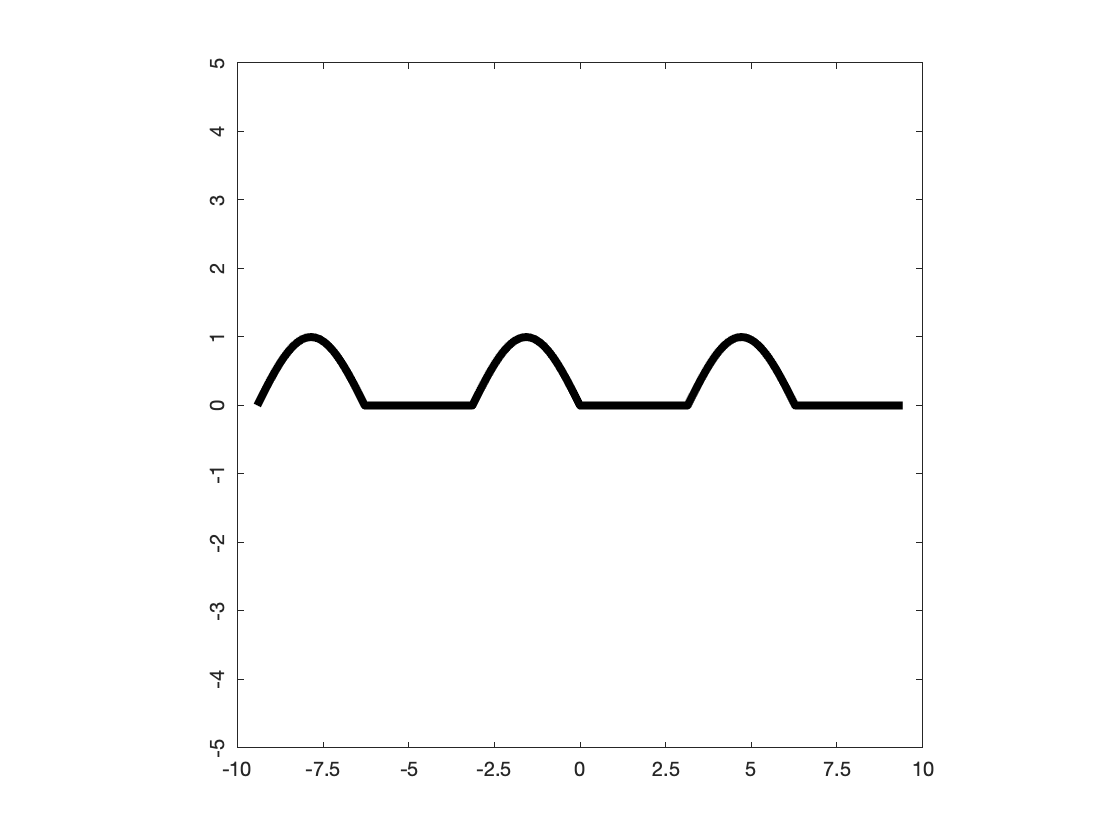

% The following code produces the above plot
figure
plot(t,f.*(f>0),'k-','LineWidth',4)
% Set graphical parameters
xlim([-10,10])
ylim([-5,5])
set(gca,'XTick',-10:2.5:10)
set(gca,'YTickLabelRotation',90)
axis square

**a) **

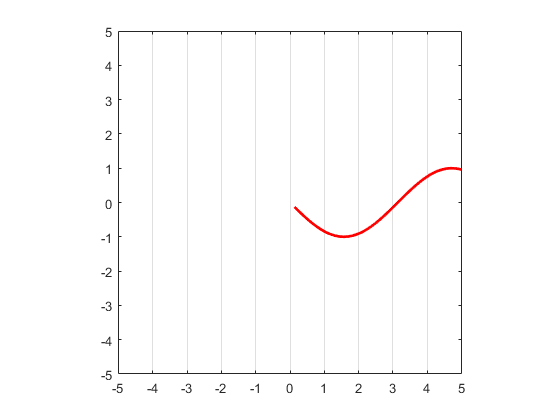

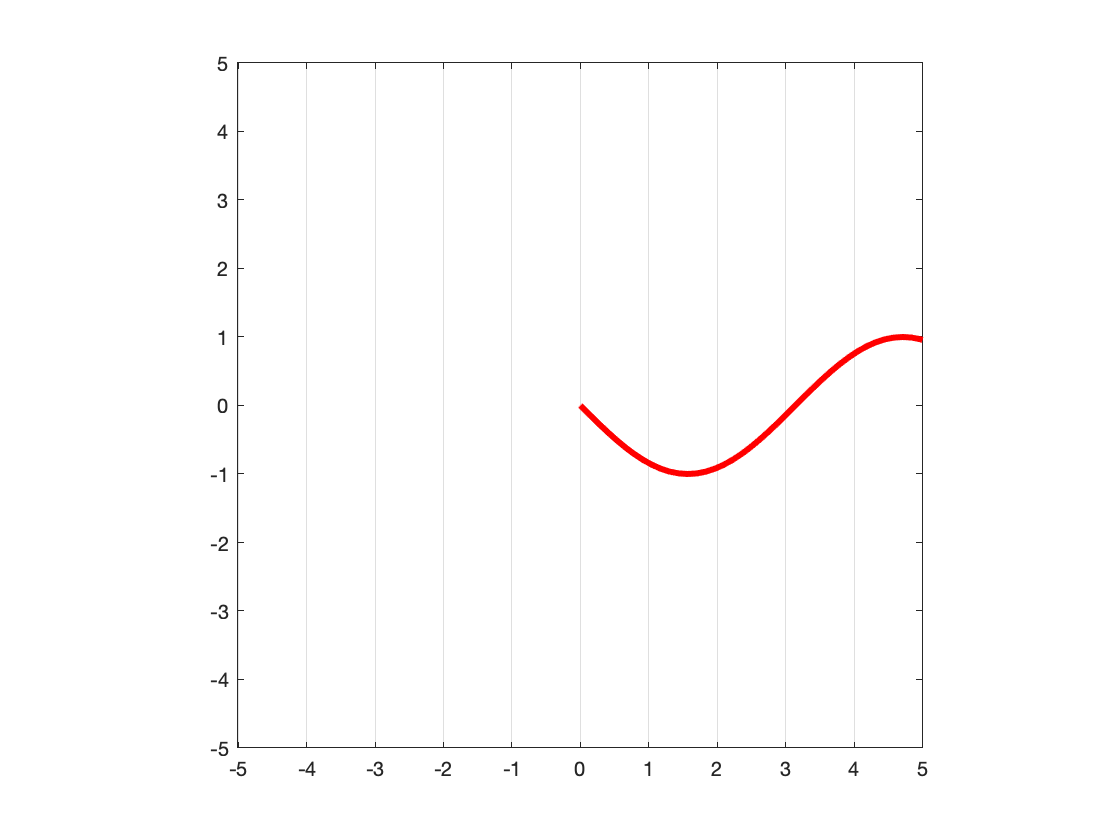


plot(t(t>=0),f(t>=0),'r-', 'LineWidth', 3)

%set(gca,'XTick',-5:5)
xlim([-5.01 5.00])
ylim([-5.00 5.00])
set(gca,'XGrid','on','YGrid','off','FontSize',10)
axis square

**b)**

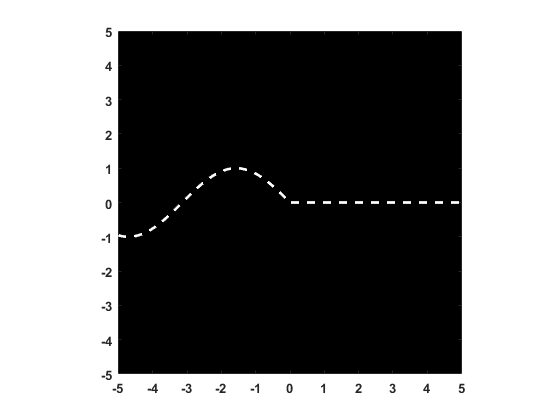

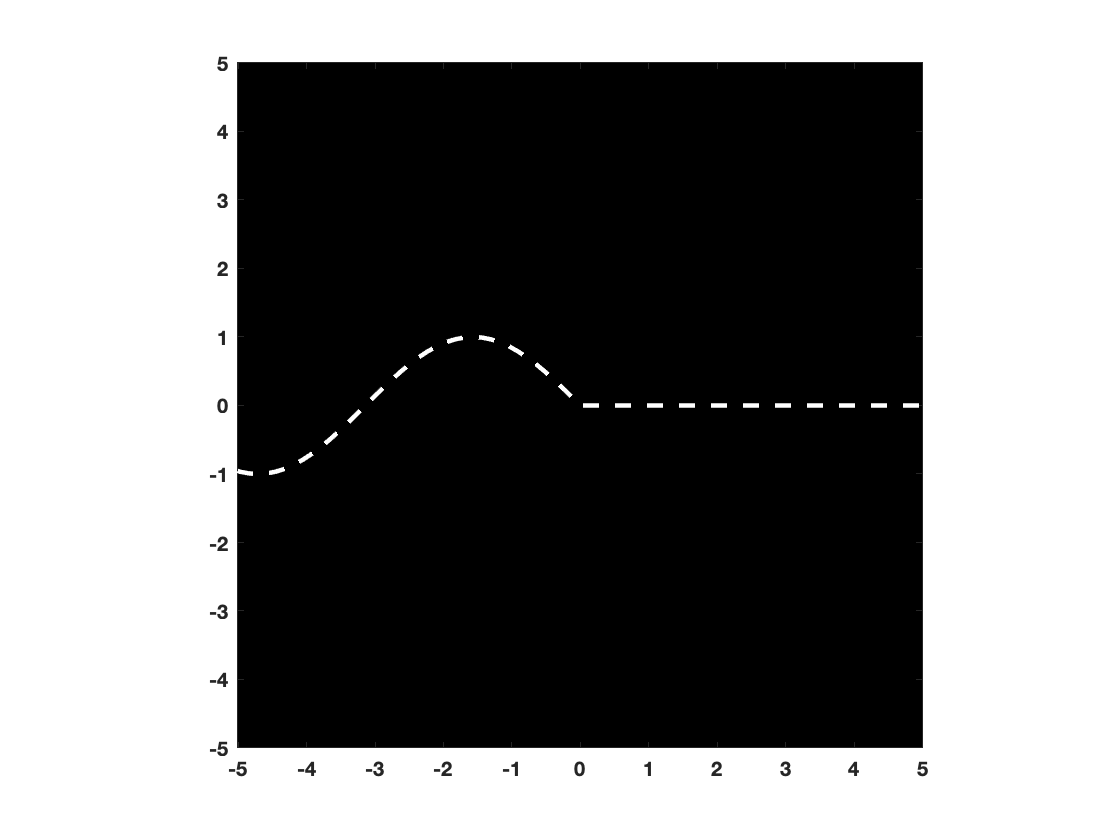


plot(t,f.*(t<0),'w--', 'LineWidth', 2.25)
xlim([-5.01 5.00])
ylim([-5.00 5.00])
set(gca, 'color', 'k','FontWeight','bold','FontSize', 10)
axis square

**c) **

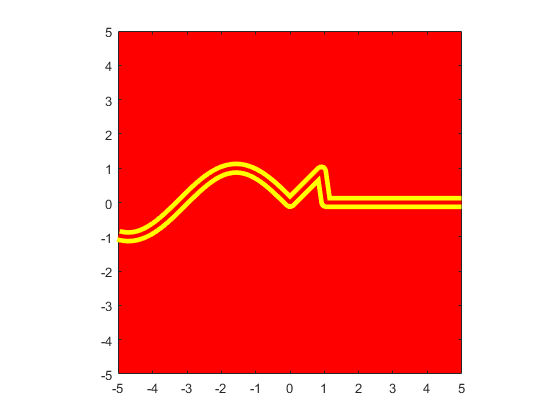

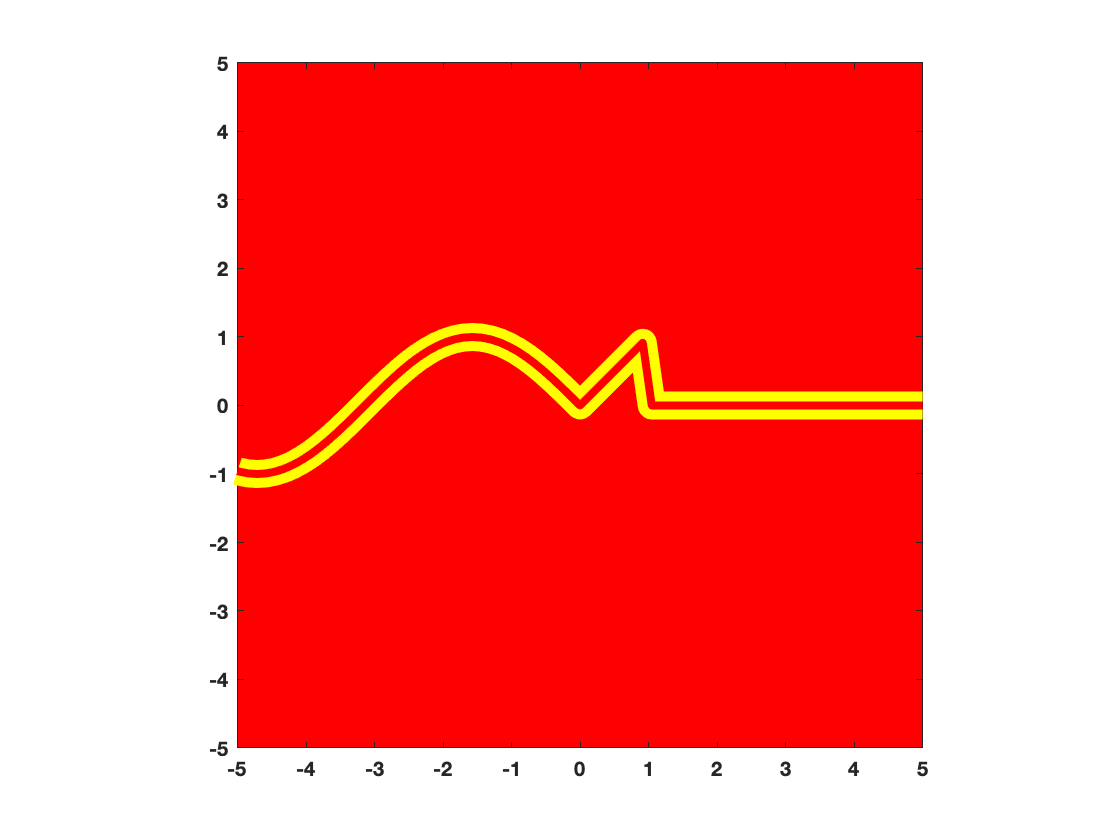

plot(t,f.*(t<=0)+abs(t.*(t>=0&t<=1)),'y-','LineWidth', 14)
hold on
plot(t,f.*(t<=0)+abs(t.*(t>=0&t<=1)),'r-','LineWidth', 4)
hold off
xlim([-5,5])
ylim([-5,5])
set(gca, 'color', 'r', 'FontWeight', 'bold')
axis square

**d) **

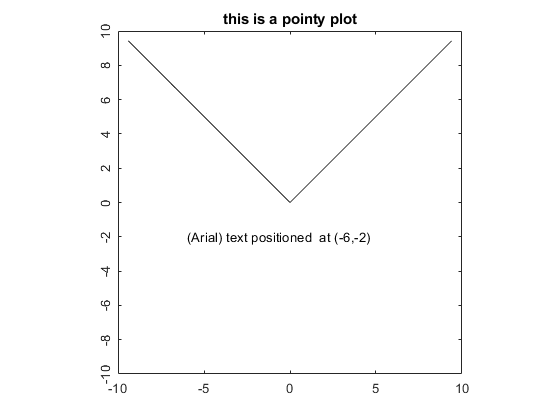

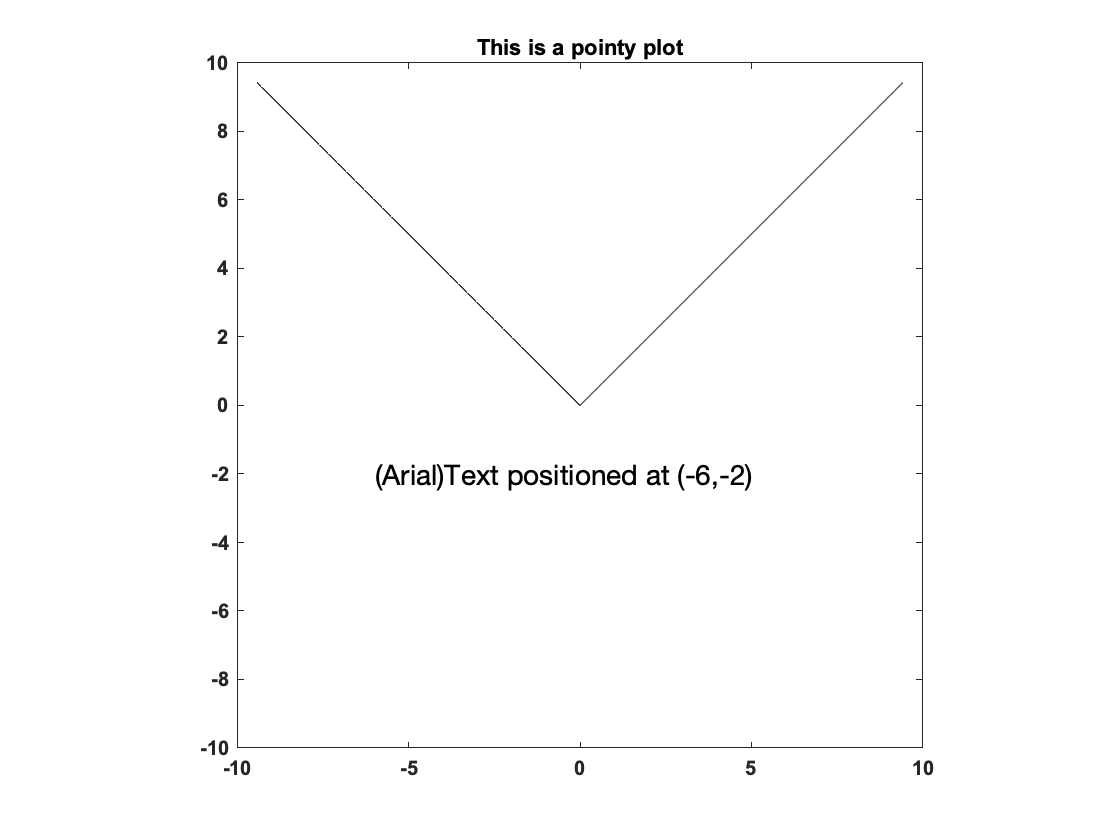


plot(t(t>=-10 & t<=0),-t(t>=-10 & t<=0),'k-')
hold on
plot(t(t>=0 & t<=10),t(t>=0 & t<=10),'k-')
hold off

title('This is a pointy plot')
text(-6,-2,'(Arial)Text positioned at (-6,-2)', 'FontSize', 14);
xlim([-10,10])
ylim([-10,10])
set(gca, 'XTick', -10:5:10, 'YTIck', -10:2:10,'FontName', 'Arial', 'FontWeight', 'bold');
axis square

**e)**

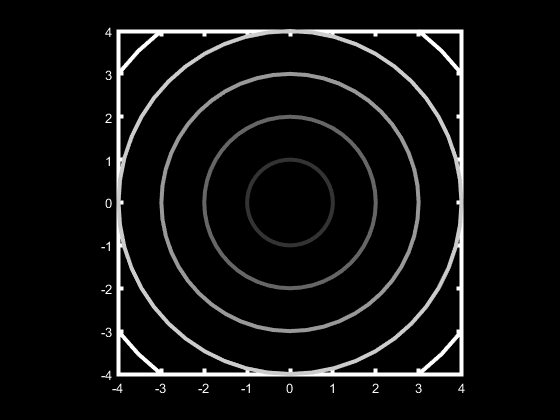

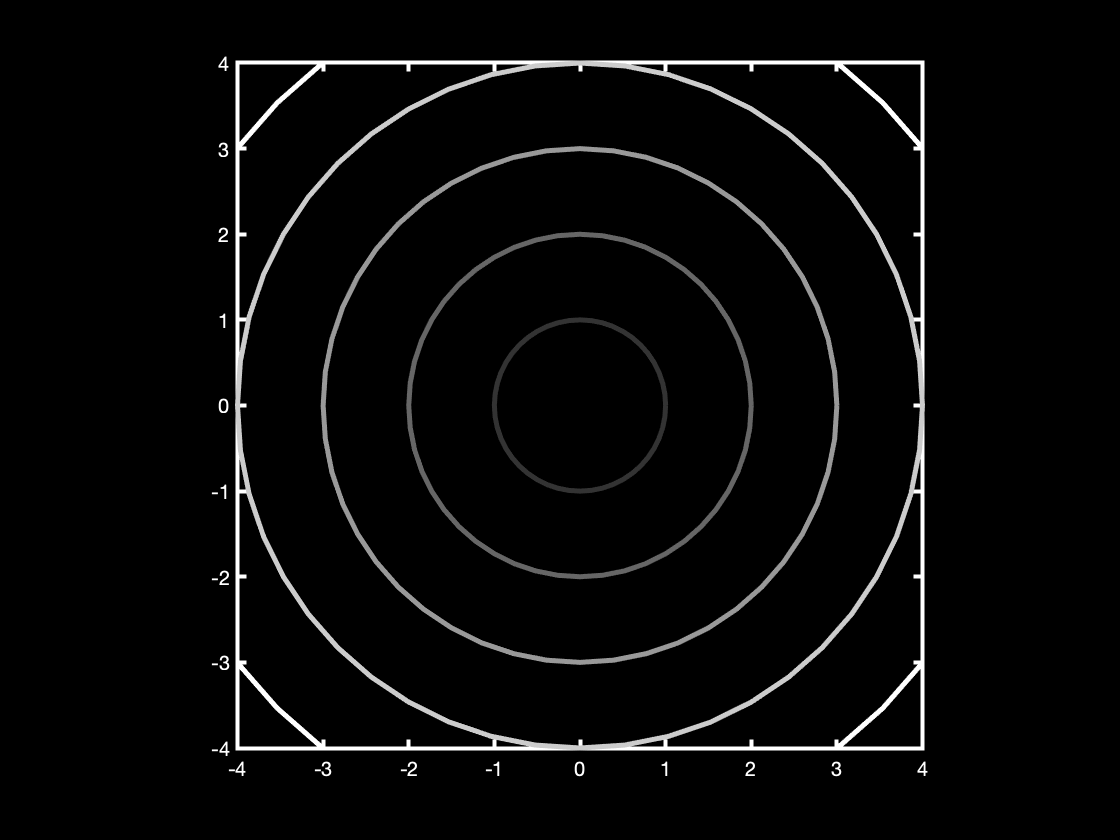


%use sin and cosine in order to make a circle 

% plot(t(t>= -2*pi & t<=2*pi),f(t>= -2*pi & t<=2*pi),'k-')
% hold on
% plot(t(t>=-2*pi & t<=2*pi), f(t>=-2*pi & t<=2*pi),'ko')
% hold off

%use x and y coordornnates using pi
%changed the coordinates using pi
fprime = cos(t);
grey = 0.2;
for r = 1:5
    plot(r*(f(t<=3*pi/2 & t>=-13*pi/24)), r*(-f(t<=2*pi&t>=0)), 'LineWidth', 2.5, 'color', [grey grey grey]);
    hold on
    grey = grey + 0.2;
end

hold off
xlim([-4,4])
ylim([-4,4])
axis square
set(gca, 'color', 'k', 'YColor', 'w', 'XColor', 'w', 'LineWidth', 2)
set(gcf, 'color', 'k' )

%time shfted x 





## PROBLEM 2 (35 pts): Fourier series approximation of a square wave

In signal processing applications, you will deal with many different types of waveforms: sine waves, triangle waves, square waves, sawtooth waves, etc. The waveform for one of these,** a square wave**, is shown below, courtesy of [this reference](https://www.electronics-tutorials.ws/waveforms/waveforms.html).

            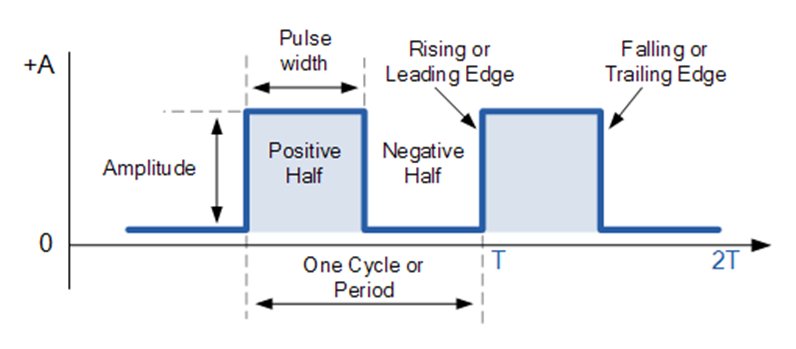

Square waves are common in microelectromechanical systems (MEMS), hardware engineering, and semiconductor applications and are characterized by the flat profile at two different values. In the above image, the square wave oscillates between a lower value (about 0) and a higher value (about "A"), though square waves can oscillate between other values (e.g. negative ones) depending on the scenario. In this problem, we will consider a square wave with a period of 2 defined over the time interval $t\in \left\lbrack 0,2\right\rbrack$. This wave has the following definition:

        
$$f\left(t\right)=\left\lbrace \begin{array}{ll}
0 & t=0,\;1,\;2\\
1 & t\in \left(0,1\right)\\
-1 & t\in \left(1,2\right)
\end{array}\right.$$


That is, the wave oscillates between -1 and 1, while be defined as 0 at the discontinuities. Graphically, the square wave looks like the following. Note: this graph depicts the one period of the square wave that we are interested in.

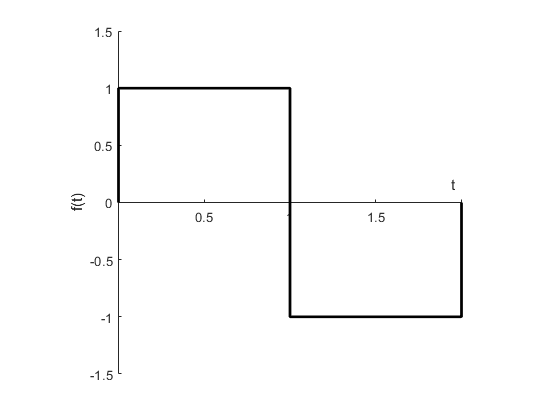

**a)** **Produce a plot** of the square wave defined above. That is, produce a plot of a square wave that oscillates between 1 and -1 with period 2 ($2L=2$) over the domain $t\in \left\lbrack 0,2\right\rbrack$.

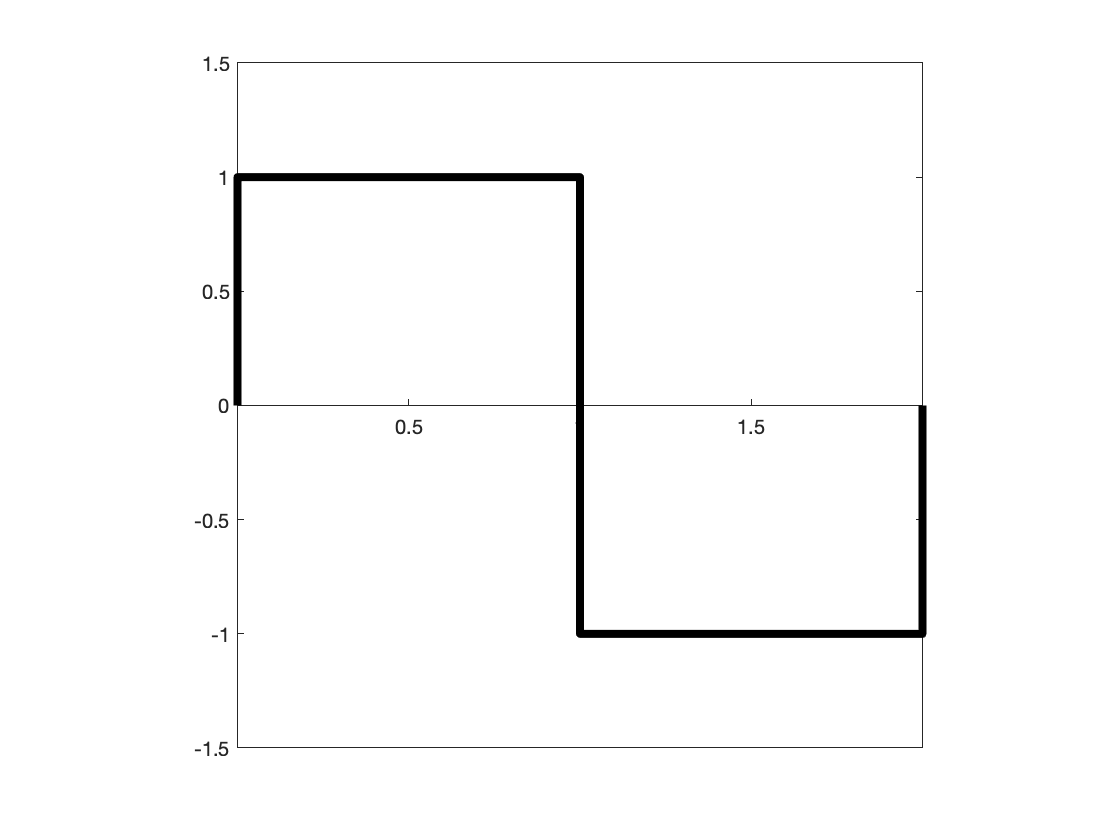

%when f(t) = 0, t = 0,1,2
%when f(t) = 1, t = (0,1)
%when f(t) = -1, t = (1,2)

% t = 0:0.01:2;
% %plot(t, (1*(t >0 * t<1) & -1*(t>1 & t<2) & 0*(t == 0 & t ==1 & t == 2)), 'k-')
% y =1;
% plot(t, 1*(t >0 * t<1), 'k-')
% hold on
% plot(t, -1*(t >1 * t<2), 'k-')
% hold on
% plot(t, 0*(t == 0 & t == 1 * t==2), 'k-')
% 
% xlim([0,2])
% ylim([-1.5,1.5])
% 
% axis square
plot([0,0,1,1,2,2],[0,1,1,-1,-1,0],'k-', 'LineWidth', 4)
xlim([0,2])
ylim([-1.5,1.5])
xlabel('t')
ylabel('f(t)')
axis square
set(gca, 'XAxisLocation', 'origin', 'XTick', 0:0.5:2)

xlabel('t')
ylabel('f(t)')







**b)** An ideal square wave (defined above) has instantaneous transitions between the high and low levels. In practice, this is never achieved because of the physical limitations (*e.g.* finite bandwidth) of the system that generates the waveform. Furthermore, for compuational purposes, a square wave is often approximated as a series of sinusoids. The **Fourier series representation of a square wave** that oscillates between 1 and -1 over a period of $2L$ is given below. 

            
$$f\left(t\right)=\frac{4}{\pi }\sum_{n\;=\;1,\;3,\;5,\;\ldotp \ldotp \ldotp }^{\infty } \frac{1}{n}\sin \left(\frac{n\pi t}{L}\right)$$


In the limit of infinite terms, $f\left(t\right)$ will exactly equal the ideal square wave defined above. However, including only "a few" terms is often sufficient to faithfully represent the square wave for practical applications and also better represent what is physically achieable.

**Create a recursive function that produces a Fourier series approximation to a square wave**. Your function should take **two inputs**: 1) a time vector corresponding to the points at which to evaluate the approximation, and 2) a scalar, `n`, determining the number of terms to include in the approximation. Your function should produce **one output**: a vector containing the fourier series approximation evaluated at the specified time points and with the specified number of terms.  

**Hint**: 

- The fourier series approximation with *1 term* is the following:

                
$$f_1 \left(t\right)=\frac{4}{\pi }\sin \left(\frac{\pi t}{L}\right)$$


- The Fourier series approximation with *4 terms* is the following:

                
$$f_4 \left(t\right)=\frac{4}{\pi }\left(\sin \left(\frac{\pi t}{L}\right)+\frac{1}{3}\sin \left(\frac{3\pi t}{L}\right)+\frac{1}{5}\sin \left(\frac{5\pi t}{L}\right)+\frac{1}{7}\sin \left(\frac{7\pi t}{L}\right)\right)$$


**Use your function**** to produce a plot of the Fourier series approximation *****with 3 terms*** over the domain $t\in \left\lbrack 0,2\right\rbrack$. Ensure your plot is clear and professional.

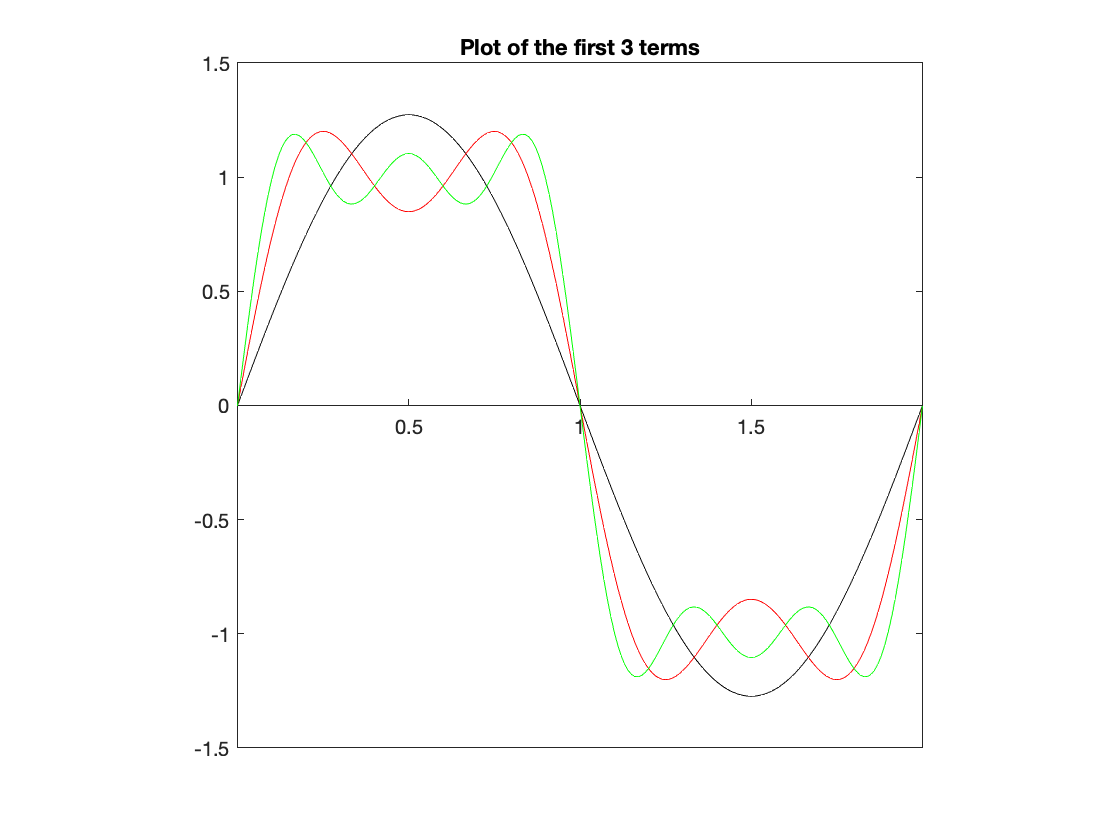

t = 0:0.01:2;
plot(t,Fourier(t,1), 'k-')
hold on
plot(t,Fourier(t,2), 'r-')
hold on
plot(t,Fourier(t,3), 'g-')
% hold on
% plot(t,Fourier(t,4), 'b-')
hold off

xlim([0,2])
ylim([-1.5, 1.5])
set(gca, 'XAxisLocation', 'origin', 'XTick', 0:0.5:2)
axis square
title('Plot of the first 3 terms')

**c)** **Using your function**, **plot** the square wave (from **a)** ) on the same axes as the Fourier appoximations with $n=1,2,3,5,\textrm{and}\;10$ terms. Ensure your plot is clear and professional.


t = 0:0.01:2;
plot([0,0,1,1,2,2],[0,1,1,-1,-1,0],'k-', 'LineWidth', 2)
hold on
plot(t,Fourier(t,1), 'k--')
hold on
plot(t,Fourier(t,2), 'r--')
hold on
plot(t,Fourier(t,3), 'k-', 'LineWidth', 3)
hold on
plot(t,Fourier(t,5), 'r-', 'LineWidth', 2)
hold on
plot(t,Fourier(t,10), 'b:', 'LineWidth', 2)
hold off

xlim([0,2])
ylim([-1.5,1.5])
axis square
set(gca, 'XAxisLocation', 'origin', 'XTick', 0:0.5:2)
title('Fourier Series approcimations of period-2 wave')
set(gca, 'color', [0.9 0.9 0.9], 'FontSizeMode', 'manual')
lgd = legend('Square wave', 'Fourier (1 term)','Fourier (2 term)','Fourier (3 term)','Fourier (5 term)','Fourier (10 term)')

lgd =   Legend (Square wave, Fourier (1 term), Fourier (2 term), Fourier (3 term), Fourier (5 term), Fourier (10 term)) with properties:

         String: {'Square wave'  'Fourier (1 term)'  'Fourier (2 term)'  'Fourier (3 term)'  'Fourier (5 term)'  'Fourier (10 term)'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6174 0.7333 0.1920 0.1726]
          Units: 'normalized'

  Show all properties


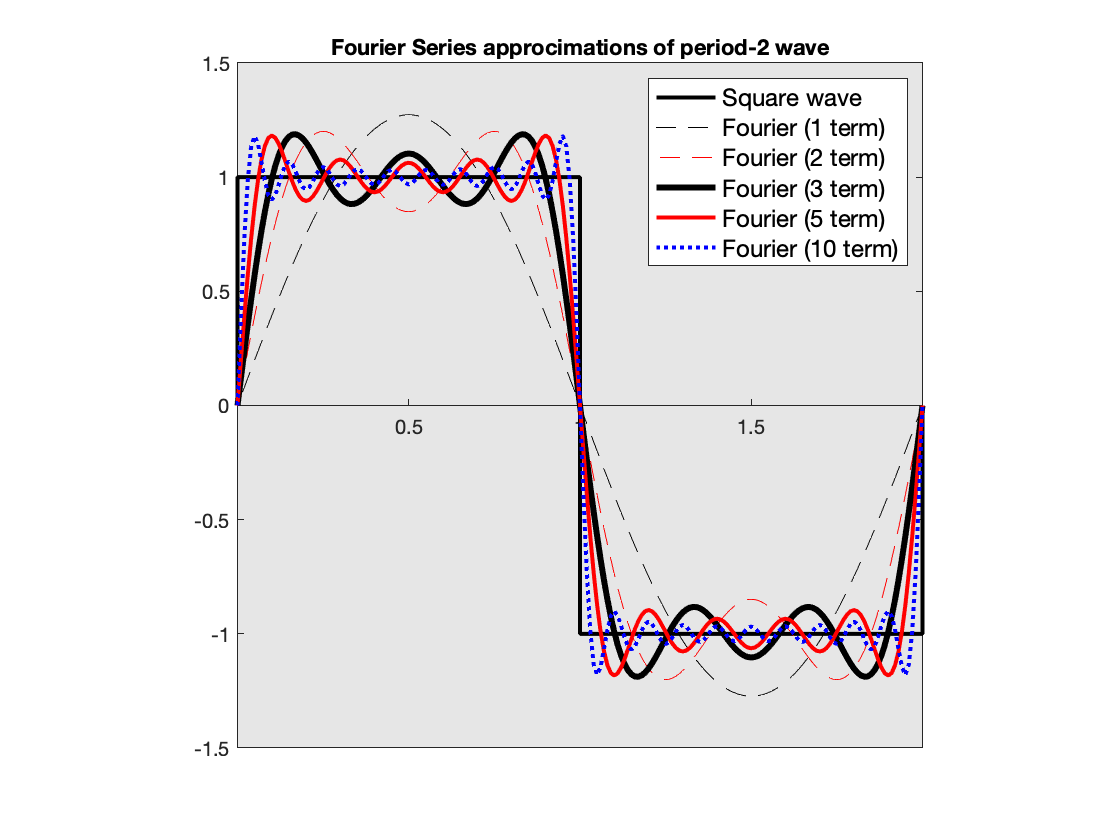

set(gcf, 'color', 'w')
set(lgd, 'color', 'w', 'FontSize', 12)

**Hint**: your output from **c)** should look similar to the following plot.

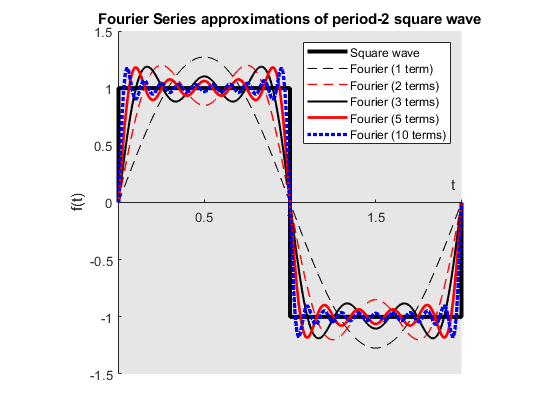

## PROBLEM 3 (30 pts): The prisoner's dilemma

Game theory, the branch of mathematics that analyzes strategies for dealing with competitive situations, has been used to simulate predator-prey competition and host-parasite co-evolution in biology, as well as population dynamics, war, and economics. One concept in game theory is the **prisoner's dilemma**, a paradoxical thought experiment that describes how two completely rational individuals might not cooperate, even if it appears that it is in their collective best interests to do so. 

**The classic prisoner's dilemma**

Two bank robbers, Mike and Dave, have been arrested and are b**eing interrogated in separate rooms**. The authorities have no other witnesses, and can only prove the case against them if they can convince at least one of the robbers to betray his accomplice and testify to the crime. Each bank robber is faced with the **choice** to *cooperate* with his accomplice and remain silent or to defect (be *hostile*) and testify for the prosecution. 

- If they **both co-operate and remain silent**, then the authorities will only be able to convict them on a lesser charge of loitering, which will mean one year in jail each (1 year for Dave + 1 year for Henry = 2 years total jail time). 

- If one testifies and the other does not, then the one who testifies will go free and the other will get three years (0 years for the one who defects + 3 for the one convicted = 3 years total). 

- However if both testify against the other, each will get two years in jail for being partly responsible for the robbery (2 years for Dave + 2 years for Henry = 4 years total jail time).

**Important note**:** the bank robbers cannot communicate with each other during this process.**

**This problem**

Here, we will consider a variation of this problem in which we will simulate 250 interactions between two individuals, where *each interaction* is **one instance of the prisoner's dilemma**. *In each interaction*, each player can choose to either **cooperate** or act **hostile** (selfish). In our case, the individuals **remember** all of their previous interactions with the other player, and **their history can inform how each approaches their current interaction.** 

***The rules dictating ******each****** interaction are as follows:***

*If both players cooperate:*

- Player 1 gains 1 "point"

- Player 2 gains 1 "point"

*If both players are hostile:*

- Player 1 loses 2 "points"

- Player 2 loses 2 "points"

*If player 1 cooperates but player 2 is hostile:*

- Player 1 loses 3 "points"

- Player 2 gains 3 "points"

*If player 1 is hostile but player 2 cooperates:*

- Player 1 gains 3 "points"

- Player 2 loses 3 "points"

In this problem, the outcome for the two individuals is determined following 250 interactions. After each interaction, the cumulative score for each individual is updated to indicate how "good" the outcome is for that player. After all 250 interactions, we will normalize each individual's total score by the number of turns (250) to get a metric of how well they performed. The **best possible final outcome for any player is 3, the worst possible final outcome is -3**. Thus, the final "score" a given player achieves indicates "how well off" they are.

**The important thing for this problem**: both players keep track of and know exactly how every previous turn has played out. For example, if one player is often hostile (i.e. a "jerk"), the other player could realize that and respond accordingly.

**a)** Think about and write out pseudocode (on your own) about how you would set up a base function that plays prisoner's dilemma, as described above. When you are ready, look at the function (`prisonerDilemma`) provided at the end of this LiveScript document and compare your code with what I have provided. Make sure you understand what occurs in each line of code in `prisonerDilemma`.**Use the code provided (**`prisonerDilemma)`** for the rest of this problem.**

**b)** `prisonerDilemma` takes **two inputs**: one function handle describing the "strategy" for each of the two players. Create the following functions (in the space provided at the end of this LiveScript document) that carry out the corresponding strategies:

- `goodPerson` - this player should always cooperate

- `badPerson` - this player should always act hostile

- `arbitraryPerson` - this player should arbitrarily decide when to cooperate or act hostile. That is, they should act randomly

***All of these functions should be named properly and have the appropriate input(s)/output(s) depending on the main function ***`prisonerDilemma`***. You should not change the code inside ***`prisonerDilemma`*** for any parts of this problem.***

**c)** **Simulate** the outcome between the following pairs:

***i)*** `goodPerson` and `goodPerson`

prisonerDilemma(@goodPerson, @goodPerson)

Final Outcome (Score)
goodPerson: 1
goodPerson: 1


***ii)*** `goodPerson` and `badPerson`

prisonerDilemma(@goodPerson, @badPerson)

Final Outcome (Score)
goodPerson: -3
badPerson: 3


***iii)*** `badPerson` and `badPerson`

prisonerDilemma(@badPerson, @badPerson)

Final Outcome (Score)
badPerson: -2
badPerson: -2


***iv)*** `arbitraryPerson` and `arbitraryPerson`

prisonerDilemma(@randomPerson, @arbitraryPerson)

Final Outcome (Score)
randomPerson: -0.16
randomPerson: -0.28


***v)*** `goodPerson` and `arbitraryPerson`

prisonerDilemma(@goodPerson, @arbitraryPerson)

Final Outcome (Score)
goodPerson: -1.08
randomPerson: 2.04


***vi)*** `badPerson` and `arbitraryPerson`

prisonerDilemma(@badPerson, @arbitraryPerson)

Final Outcome (Score)
badPerson: 1
randomPerson: -2.6


**d)** **Create function** (in the space provided at the end of this LiveScript document) called `massiveRetaliation` that describes an individual who *will always cooperate* **until** the *other individual* *acts* *hostile*. From that point on, `massiveRetaliation` will **only** act hostile for the remainder of the 250 interactions. **Simulate the outcome between the following pairs**:

*i)* `goodPerson` and `massiveRetaliation`

prisonerDilemma(@goodPerson, @massiveRetalliation)

Final Outcome (Score)
goodPerson: 1
massiveRetalliation: 1


*ii)* bad`Person` and `massiveRetaliation`

prisonerDilemma(@badPerson, @massiveRetalliation)

Final Outcome (Score)
badPerson: -1.9
massiveRetalliation: -2.02


*iii)* `arbitraryPerson` and `massiveRetaliation`

prisonerDilemma(@arbitraryPerson, @massiveRetalliation)

Final Outcome (Score)
randomPerson: -2.2
massiveRetalliation: 0.2


**e)** **Create a function **(in the space provided at the end of this LiveScript document)** describing how you would approach these interactions**, if you were one of the individuals.

**Note**: there is no "correct" answer to this problem. Produce any function (*that potential uses your history and/or the other player's history*) that you think could be a good way to approach this situation. **Please also describe below (in only a few sentences) what your strategy would be.**

***Your response:***

`I tried initially finding a way to check if the previous inputs are something, then you should play this. However after looking at previous results, no matter what, as long as you are a bad player throughout, you won't lose. Due to this I believe it is best to be a bad player no matter what the other player plays. In all of the scenarios you dont lose, and in 3/4 of them you win so I believe this is enough to count as a good code. `

**Name your function**: "pd" followed by the last 6 digits of your student ID number,. For example: If your ID number is 53218574, your function would be named: `pd218574`

**f) Save your function as a function (**`.m`**) file** and submit it with the .PDF and `.mlx` files of this homework. Remember that when saving custom functions, the file name must match the function name.

**g) Simulate the outcome between the following pairs**:

*i)* `goodPerson` and `<your function>`

prisonerDilemma(@goodPerson, @pd30808116)

*ii)* bad`Person` and `<your function>`

prisonerDilemma(@badPerson, @pd30808116)

Final Outcome (Score)
goodPerson: 0.84
pd30808116: 1.08


*iii)* `arbitraryPerson` and `<your function>`

prisonerDilemma(@arbitraryPerson, @pd30808116)

Final Outcome (Score)
badPerson: -2
pd30808116: -2


*iv) *`massiveRetaliation` and `<your function>`

prisonerDilemma(@massiveRetalliation, @pd30808116)

Final Outcome (Score)
arbitraryPerson: -1.18
pd30808116: 0.26


## Problem Set 7: functions stored below

**Use the space below for PROBLEM 2).**

function ft = Fourier(t,n)

Final Outcome (Score)
massiveRetalliation: -2.02
pd30808116: -1.9


    %t: time vector for approximation
    %n: amount of terms that are used
     
    if n == 1 
        ft = (4/pi) * sin((pi*t));
    else 
        ft = (4/pi) * ((1/(2*n-1)*(sin((2*n-1)*pi*t)))) + Fourier(t,n-1);
    end
    
end










**Use the space below for PROBLEM 3): **

- ***Base function for "the prisoner's dilemma"***

function prisonerDilemma(player1,player2)
    % This function plays the prisoners dilemma between player 1 and player
    % 2. Specifically it describes the outcome from 250 "player
    % iteractions," where the manner in which one player responds to the
    % other depends upon their "history." That is, if one player is a
    % "jerk," the other player will realize that as more and more
    % interactions occur.
    % 
    % NOTE 1. The inputs to this function are two function handles. One describing
    % how player 1 will "play." The second describing how player 2 will
    % "play."
    % 
    % NOTE 2. The options for "how" a player will respond are as follows: 
    % If a player wishes to cooperate:  the player's function will output 1
    % If a player wishes to be hostile: the player's function will output 0
    % 
    % NOTE 3. After each interaction, each player's "score" will be updated
    % depending on how well from them that interaction went. A high score
    % corresponds to a successful outcome for that player
    % 
    % NOTE 4. The rules for the interactions are as follows:
    % A) If both players cooperate (both output 1)
    %       Player 1's score: increase by 1
    %       Player 2's score: increase by 1
    % B) If both players are hostile (both output 0)
    %       Player 1's score: decrease by 2
    %       Player 2's score: decrease by 2
    % C) If player 1 cooperates but player 2 is hostile
    %    (Player 1 outputs 1, player 2 outputs 0)
    %       Player 1's score: decrease by 3
    %       Player 2's score: increase by 3
    % D) If player 1 is hostile but player 2 cooperates
    %    (Player 1 outputs 0, player 2 outputs 1)
    %       Player 1's score: increase by 3
    %       Player 2's score: decrease by 3
    
    
    % Variable storing number of interactions to consider. Here, we will
    % consider 250 turns.
    numTurns = 50;
    
    % Preallocate vector to store the output from each turn
    % Note: we will preallocate as NaN to avoid confusion because each
    % entry (corresponding to an interaction) will be either 0 or 1.
    p1_hist = nan(1,numTurns);
    p2_hist = nan(1,numTurns);

    % Stores the score of each player
    p1_score = 0;
    p2_score = 0;
    
    % Each successive iteration of this FOR loop corresponds to another
    % interaction between players
    for k = 1:numTurns
            
        % Determine how each player will play in the k-th interaction
        % Note: the output values will either be 0 or 1, corresponding to
        % NOTE 2, above
        % FIRST INPUT (in each): is THAT player's previous moves
        % SECOND INPUT (in each): is the OTHER player's previous moves
        out1 = player1(p1_hist(~isnan(p1_hist)),p2_hist(~isnan(p2_hist)));
        out2 = player2(p2_hist(~isnan(p2_hist)),p1_hist(~isnan(p1_hist)));

        % Update player 1 score based on NOTE 4
        p1_score = p1_score - 3 + 6*(out1<out2) + ...
            (out2==out1)*(4*(out1==1) + (out1==0));
        
        % Update player 2 score based on NOTE 4
        p2_score = p2_score - 3 + 6*(out1>out2) + ...
            (out2==out1)*(4*(out2==1) + (out2==0));

        % Store current action in vector containing histories of each
        % player's moves
        p1_hist(k) = out1;
        p2_hist(k) = out2;

    end
    disp('Final Outcome (Score)');
    disp(strcat([func2str(player1),': ',num2str(p1_score/numTurns)]));
    disp(strcat([func2str(player2),': ',num2str(p2_score/numTurns)]));
end

- ***Function for a "good person"***

function goodChoice = goodPerson(p1_past, p2_past) 
    goodChoice = 1;
    
end









- ***Function for a "bad person"***

function badChoice = badPerson(p1_past, p2_past)
    badChoice = 0;
    
end









- ***Function for an "arbitrary person"***

function randomChoice = arbitraryPerson(p1_past, p2_past)
    randomChoice = randi([0,1]);
end








- ***Function for an "massiveRetaliation***

function choice = massiveRetalliation(p1_past, p2_past)
    %check if in their past, there is a history of hostility 
    if any(p2_past == 0)
        choice = 0;
    else 
        choice = 1;
    end
  
end









- ***Function describing your approach to the prisoner's dilemma***

%wont lose if you are just a bad person the whole time
% if both players play two 1's in a row then you switch to playing a zero

function choice = pd30808116(p1_past, p2_past)
p1_past = p1_past(~isnan(p1_past));    
p2_past = p2_past(~isnan(p2_past));

%first checks if theyre empty and if so just input a zero
    if isempty(p1_past) || isempty(p2_past)
        choice = 0; 
    elseif length(p1_past) == 1 || length(p2_past) == 1
        choice = 0;
    else 
        if p2_past(end) == 1 && p2_past(end-1) == 1
            choice = 1; 
        else
            choice = 0;
        end
    end  
end






